% Setting initial values
clear;clc;
TR = 50;
T1 = 1000;
T2_dephasing = 50;
n=6;
TE = linspace(5,15,n);
Alpha = linspace(pi/12,pi/2,n);
%M_initial = ((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha)).*exp(-TE/T2_dephasing); 
%M = 1+(M_initial-1).*exp(-(TR-TE)/T1);

% Iteration: N times of RF
N = 10;
M_initial = ones(N,n);
M = zeros(N,n);
result=ones(2*N+1,n);
for N=1:N
    if N>1
        M_initial(N,:) = M(N-1,:).*((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha)).*exp(-TE/T2_dephasing); 
    else
        M_initial(N,:) = ones(1,n).*((1-exp(-TR/T1)).*sin(Alpha))./(1-exp(-TR/T1).*cos(Alpha)).*exp(-TE/T2_dephasing);
    end
    M(N,:) = 1+(M_initial(N,:)-1).*exp(-(TR-TE)/T1); 
    result(2*N,:) = M_initial(N,:);
    result(2*N+1,:) = M(N,:);
end

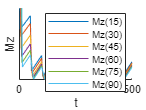

% Plot result
figure();
T = zeros(2*N+1,n);
for i=1:N
    T(2*i-1,:) = (i-1)*TR;
    T(2*i,:) = (i-1)*TR+TE;    
end
T(21,:) = TR*10;
hold on;
for i=1:n
    plot(T(:,i),result(:,i));
end
%LineName = ['Mz(10)';'Mz(20)';'Mz(30)';'Mz(40)';'Mz(50)';'Mz(60)';'Mz(70)';'Mz(80)';'Mz(90)'] ;
LineName = ['Mz(15)';'Mz(30)';'Mz(45)';'Mz(60)';'Mz(75)';'Mz(90)'] ;
legend(LineName);
axis([min(T(:)) max(T(:)) 0 0.2]);
ylabel('Mz'); xlabel('t')
set(gca, 'YTick', []);

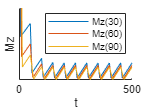

figure();
hold on;
plot(T(:,2),result(:,2))
plot(T(:,4),result(:,4))
plot(T(:,6),result(:,6))
LineName = ['Mz(30)';'Mz(60)';'Mz(90)'] ;
legend(LineName);
axis([min(T(:)) max(T(:)) 0 0.2]);
ylabel('Mz'); xlabel('t')
set(gca, 'YTick', []);

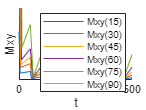

% Mxy = Mz * tan = M * sin
Mxy = result.*tan(Alpha);
figure();
hold on;
for i=1:n
    plot(T(:,i),Mxy(:,i));
end
LineName = ['Mxy(15)';'Mxy(30)';'Mxy(45)';'Mxy(60)';'Mxy(75)';'Mxy(90)'] ;
legend(LineName);
axis([min(T(:)) max(T(:)) 0 0.4]);
ylabel('Mxy'); xlabel('t')
set(gca, 'YTick', []);